# Problem 1

addpath(genpath(fileparts(which('pathfile.m'))))
interr = 'latex';
% interr = 'none';
set(groot,'defaulttextinterpreter',interr);
set(groot, 'defaultAxesTickLabelInterpreter',interr);
set(groot, 'defaultLegendInterpreter',interr);
R_E = 6378.1363;
R_M = 1738.2;
mu_E = 398600.4415;
mu_M = 4902.8005821478;
a_M = 384400.00; % moon SMA around Earth

## Part a)

Hohmann Transfer Characterisitcs

rp_T_mag = 250 + R_E, ra_T_mag = a_M

rp_T_mag = 6.6281e+03

ra_T_mag = 384400

a_T = (rp_T_mag + ra_T_mag)/2

a_T = 1.9551e+05

e_T = 1 - rp_T_mag/a_T

e_T = 0.9661

v1_n_mag = sqrt(mu_E*(2/rp_T_mag - 1/a_T))

v1_n_mag = 10.8737

v1_n = [v1_n_mag 0]'

v1_n =    10.8737
         0


v2_0_mag = sqrt(mu_E*(2/ra_T_mag - 1/a_T))

v2_0_mag = 0.1875

v2_0_R = [0 v2_0_mag]'

v2_0_R =          0
    0.1875


n_T = sqrt(mu_E/a_T^3)

n_T = 7.3030e-06

Moon Orbit about Earth

v_M_mag = sqrt((mu_E)/a_M)

v_M_mag = 1.0183

v_M_R = [0,v_M_mag]'

v_M_R =          0
    1.0183


Departure Parking Orbit

r1_mag = 250 + R_E

r1_mag = 6.6281e+03

v1_0_mag = sqrt(mu_E/r1_mag)

v1_0_mag = 7.7548

v1_0 = v1_0_mag * [1 0]'

v1_0 =     7.7548
         0



dv1 = v1_n-v1_0, dv1_mag = norm(dv1)

dv1 =     3.1188
         0


dv1_mag = 3.1188

Arrival Parking orbit

rp_M = 195 + R_M

rp_M = 1.9332e+03

Arrival Hyperbolic Orbit

v_inf_M = v2_0_R - v_M_R

v_inf_M =          0
   -0.8308


v_inf_M_mag = norm(v_inf_M)

v_inf_M_mag = 0.8308

v2_n_mag = sqrt(mu_M/rp_M)

v2_n_mag = 1.5925

dv2_mag = sqrt(v_inf_M_mag^2 + 2*mu_M/rp_M) - v2_n_mag

dv2_mag = 0.8080

Total

dvtotal_mag = dv1_mag + dv2_mag

dvtotal_mag = 3.9268

Post Encounter Orbit

a_h = -mu_M/v_inf_M_mag^2

a_h = -7.1030e+03

e_h = 1 - rp_M/a_h

e_h = 1.2722


delta = 2*(asin(1/e_h)),delta_deg = rad2deg(delta)

delta = 1.8088

delta_deg = 103.6376

ths_inf = acos(-1/e_h), ths_inf_deg = rad2deg(ths_inf)

ths_inf = 2.4752

ths_inf_deg = 141.8188


v2_n_mag = sqrt(v_M_mag^2 + v_inf_M_mag^2 - 2*v_M_mag*v_inf_M_mag*cos(delta))

v2_n_mag = 1.4581


gamma_2_n = asin(v_inf_M_mag/v2_n_mag * sin(delta)), gamma_2_n_deg = rad2deg(gamma_2_n)

gamma_2_n = 0.5868

gamma_2_n_deg = 33.6223

v2_n_R = v2_n_mag*[sin(gamma_2_n);cos(gamma_2_n)]

v2_n_R =     0.8074
    1.2142


v_2_0_R = [0 v2_0_mag]'

v_2_0_R =          0
    0.1875


dveq_R = v2_n_R - v_2_0_R

dveq_R =     0.8074
    1.0267


dveq_mag = norm(dveq_R)

dveq_mag = 1.3061

ths_2_n = atan((ra_T_mag * v2_n_mag^2 / mu_E)*sin(gamma_2_n)*cos(gamma_2_n)...
    /((ra_T_mag * v2_n_mag^2 / mu_E)*cos(gamma_2_n)^2-1))

ths_2_n = 1.1512

ths_2_n_deg = rad2deg(ths_2_n)

ths_2_n_deg = 65.9585


iCr2 = [cos(pi), -sin(pi); sin(pi) cos(pi)]

iCr2 =    -1.0000   -0.0000
    0.0000   -1.0000


v2_0 = iCr2 * v2_0_R

v2_0 =    -0.0000
   -0.1875


v2_n = iCr2 * v2_n_R

v2_n =    -0.8074
   -1.2142


dveq = v2_n - v2_0

dveq =    -0.8074
   -1.0267



a_post = -mu_E*(v2_n_mag^2 - 2*mu_E/ra_T_mag)^-1

a_post = -7.6283e+06

e_post = sqrt((ra_T_mag * v2_n_mag^2/mu_E -1)^2*cos(gamma_2_n)^2+sin(gamma_2_n)^2)

e_post = 1.0352

rp_post = a_post*(1-e_post)

rp_post = 2.6853e+05


dv_d = -dveq, dv_d_mag = norm(dv_d)

dv_d =     0.8074
    1.0267


dv_d_mag = 1.3061

v2_d = v2_0

v2_d =    -0.0000
   -0.1875


v2_o = v2_n

v2_o =    -0.8074
   -1.2142


dgamma2 = 0 - gamma_2_n

dgamma2 = -0.5868

[alpha,beta] = alphabeta(norm(v2_o),norm(v2_d),norm(-dveq),dgamma2)

alpha = 3.0620

beta = 0.0796

alpha_deg = rad2deg(alpha), beta_deg = rad2deg(beta)

alpha_deg = 175.4411

beta_deg = 4.5589

## Part b)

Transfer Orbit Characteritics

trans_angle = 173 * pi / 180;

r1_mag = R_E + 150

r1_mag = 6.5281e+03

r2_mag = a_M

r2_mag = 384400

ta1 = 0

ta1 = 0

ta2 = trans_angle

ta2 = 3.0194


e_T = (r2_mag/r1_mag - 1)*(1-r2_mag/r1_mag * cos(ta2))^-1

e_T = 0.9737

a_T = r1_mag/(1-e_T)

a_T = 2.4858e+05

rp = r1_mag

rp = 6.5281e+03

ra = a_T*(1+e_T)

ra = 4.9064e+05

n = sqrt(mu_E/a_T^3)

n = 5.0940e-06

period = 2*pi/n, period_hr = period/3600, period_day = period/3600/24

period = 1.2335e+06

period_hr = 342.6253

period_day = 14.2761

[TOF_T,dt1,dt2] = timeofflight(ta1,ta2,a_T,e_T,r1_mag,mu_E)

TOF_T = 2.6708e+05

dt1 = 0

dt2 = 2.6708e+05

TOF_T_day = TOF_T/3600/24

TOF_T_day = 3.0912

energy_T = -mu_E/(2*a_T)

energy_T = -0.8017


n_M = sqrt(mu_E/a_M^3)

n_M = 2.6491e-06

phase = pi - n_M*TOF_T, phase_deg = rad2deg(phase)

phase = 2.4341

phase_deg = 139.4630

v1_0_mag = sqrt(mu_E/r1_mag)

v1_0_mag = 7.8140

v1_n_mag = sqrt(mu_E*(2/r1_mag - 1/a_T))

v1_n_mag = 10.9779

dv1_mag = v1_n_mag - v1_0_mag

dv1_mag = 3.1639

## Part c)

r2_mag

r2_mag = 384400

v2_0_mag = sqrt(mu_E*(2/r2_mag - 1/a_T))

v2_0_mag = 0.6859

h_T = sqrt(mu_E*a_T*(1-e_T^2))

h_T = 7.1665e+04

gamma2_0 = asin(mu_E*e_T/v2_0_mag/h_T * sin(ta2)), gamma2_0_deg = rad2deg(gamma2_0)

gamma2_0 = 1.2955

gamma2_0_deg = 74.2271

pi-gamma2_0

ans = 1.8461

gamma2_0_check = acos(sqrt(mu_E*a_T*(1-e_T^2))/r2_mag/v2_0_mag)

gamma2_0_check = 1.2955


v2_n_mag = v2_0_mag

v2_n_mag = 0.6859

gamma2_n = -gamma2_0

gamma2_n = -1.2955

c = r2_mag*v2_n_mag^2/mu_E;
e_T2 = sqrt((c - 1)^2 * cos(gamma2_n)^2 + sin(gamma2_n)^2)

e_T2 = 0.9737

ta2_n = -ta2

ta2_n = -3.0194

ta2_n_deg = rad2deg(ta2_n)

ta2_n_deg = -173

dw = 2*pi + (ta2_n - ta2)

dw = 0.2443


v2_0 = v2_0_mag*[sin(gamma2_0); cos(gamma2_0)]

v2_0 =     0.6600
    0.1864


v2_n = v2_n_mag*[sin(gamma2_n); cos(gamma2_n)]

v2_n =    -0.6600
    0.1864


dv2_eq = v2_n-v2_0

dv2_eq =    -1.3201
         0


dv2_eq_mag = norm(dv2_eq)

dv2_eq_mag = 1.3201


dgamma = gamma2_n - gamma2_0, dgamma_deg = rad2deg(dgamma)

dgamma = -2.5910

dgamma_deg = -148.4542

[alpha,beta] = alphabeta(v2_0_mag,v2_n_mag,dv2_eq,dgamma), alpha = - alpha

alpha = 2.8663

beta = 0.2753

alpha = -2.8663

alpha_deg = rad2deg(alpha)

alpha_deg = -164.2271

beta_deg = rad2deg(beta)

beta_deg = 15.7729


v_M_mag = sqrt(mu_E/a_M)

v_M_mag = 1.0183

v_M = v_M_mag*[0;1]

v_M =          0
    1.0183


v2_inf_0 = v2_0 - v_M

v2_inf_0 =     0.6600
   -0.8319


v2_inf_mag = norm(v2_inf_0)

v2_inf_mag = 1.0619

v2_inf_n = v2_n - v_M

v2_inf_n =    -0.6600
   -0.8319



a_h = -mu_M/v2_inf_mag^2

a_h = -4.3478e+03

L = acos(dot(v2_inf_n,v2_inf_0)/v2_inf_mag^2)

L = 1.3414

% delta = pi-L
delta = 2*asin(v2_0_mag/v2_inf_mag * sin(gamma2_0))

delta = 1.3414


delta_deg = rad2deg(delta)

delta_deg = 76.8594

e_h = 1/sin(delta/2)

e_h = 1.6089

rp_h = a_h*(1-e_h)

rp_h = 2.6472e+03

alt_p = rp_h - R_M

alt_p = 909.0458

## Part d)

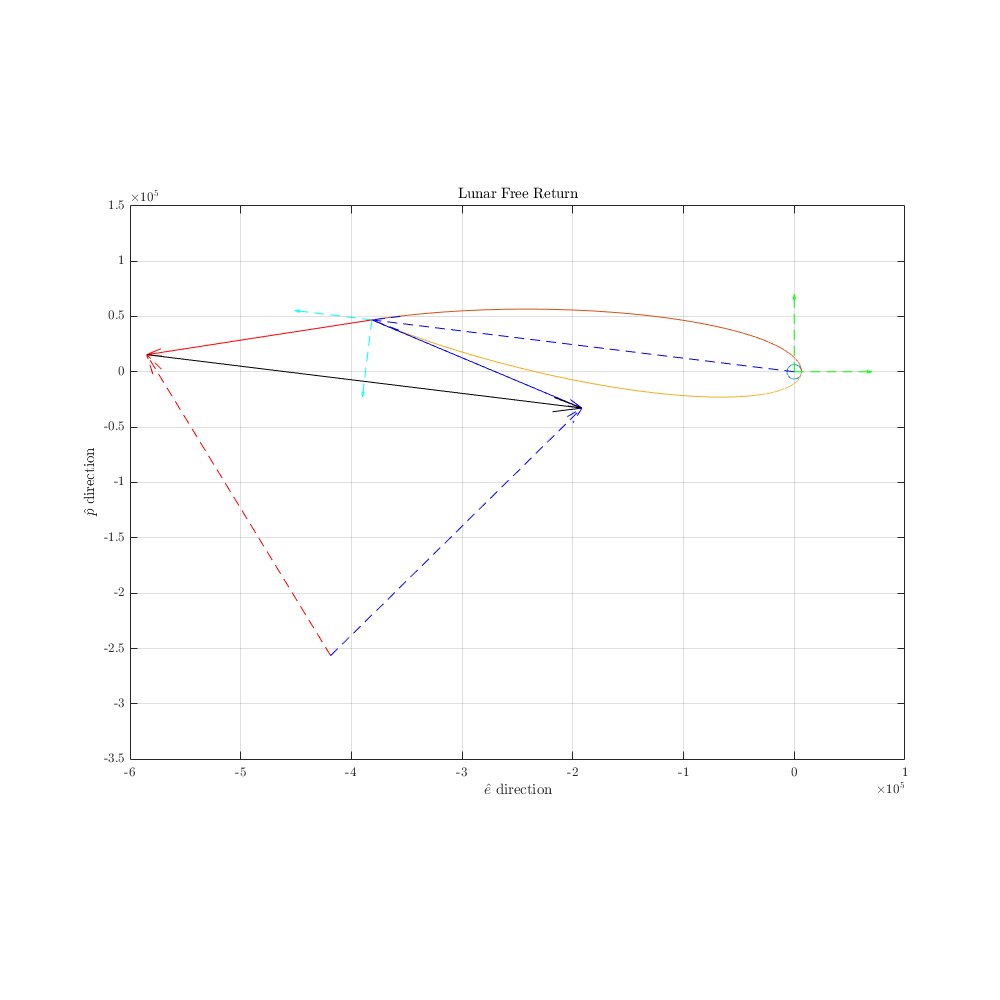

% plotorbit(ai,ei,ths1,ths2,rotate) % plot orbit inputs
plotorbit(rp,0,0,2*pi,0) % parking orbit
hold on
% plotorbit(a_M,0,0,2*pi,0) % Moon orbit
plotorbit(a_T,e_T,0,ta2,0)
plotorbit(a_T,e_T,-ta2,0,dw)
plotunit([0,0],0,'g--',10)
plotpos(a_T,e_T,ta2,'b--',0,10)
plotvel(a_T,e_T,ta2,v2_0,'r',0,0,3e5)
plotvel(a_T,e_T,ta2,v2_n,'b',0,0,3e5)
plotvel(a_T,e_T,ta2,dv2_eq,'k',[1;v2_0],0,3e5)
plotvel(a_T,e_T,ta2,v2_inf_0,'r--',[1;v_M],0,3e5)
plotvel(a_T,e_T,ta2,v2_inf_n,'b--',[1;v_M],0,3e5)
xlim([-6 1]*1e5),ylim([-3.5 1.5]*1e5)
set(gcf,'position',[0,0,1000,1000])
title('Lunar Free Return')
xlabel('$\hat{e}$ direction')
ylabel('$\hat{p}$ direction')